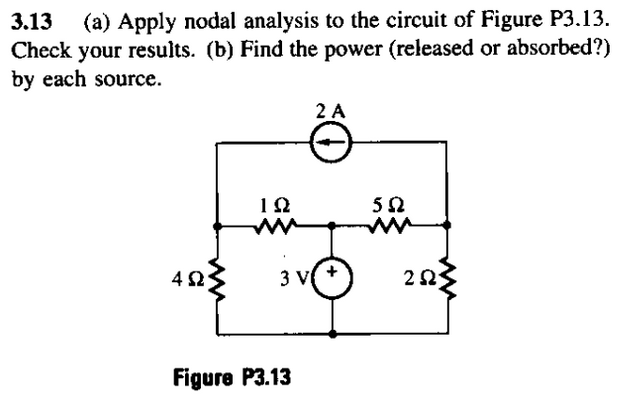

Para hacer un analisis nodal debemos seleccionar un nodo de referencia y nombrar los nodos que identificamos:

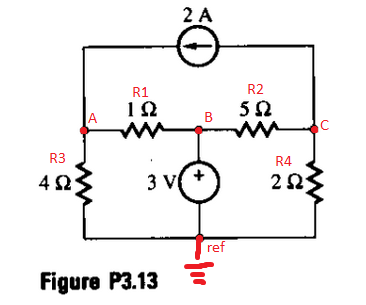

clc, clear, close all
format short g

R1 = 1;
R2 = 5;
R3 = 4;
R4 = 2;

Vf = 3;
If = 2;

Vemos que debido a la fuente de 3 V, en el nodo B debe haber 3V, po lo tanto nos quedan dos nodos por analizar, el A y C. procedemos a hacer el analisis nodal:

syms Va
V_a = double(solve((Va/4)+((Va-3)/1)-If==0,Va))

V_a =      4


syms Vc
V_c = double(solve((Vc/2)+((Vc-3)/5)+If==0,Vc))

V_c =     -2


Ahora que tenemos las tensiones en cada nodo, hayamos la potencia en los elementos activos:

p_if = -(V_a-V_c)*If

p_if =    -12


para calcular la potencia en la fuente de tension primero calculamos la corriente en los resistores r1 y r2 para hacer LCK:

I_r1 = (V_a-Vf)/R1

I_r1 =      1


I_r2 = (Vf-V_c)/R2

I_r2 =      1


vemos que por ambos resistores pasa 1A, es decir que la fuente de tension no está entregando corriente, por lo que no esta entregando potencia. Por ultimo verificamos en el simulador: